MZW_st.name='MZW'; 
MZW_st.lat=40.5383;
MZW_st.lon=-106.677;
MZW_st.alt=3243;
MZW_st.env='Mt';
MZW_st.footp='F';


MZW_rd=read_betsy('MZW_head',MZW_st.name);

datevec(MZW_rd.Time(1))

ans =         1993          10           2           0           0           0

datevec(MZW_rd.Time(end))

ans =         2009          10           1           0           0           0

prctile(MZW_rd.U_S,[5 50 95])

ans =    27.9175   65.3400   92.1713

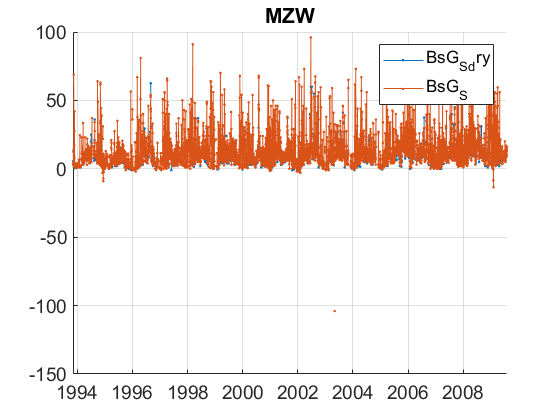

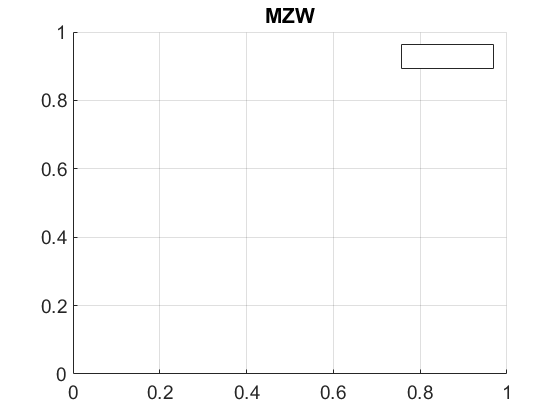

plotFigControl(MZW_rd,MZW_st.name);

% 1 size cut, ok
% sc: ok, max in summer, few negatives



% % lambdaSC=[450;550;700]*ones(1,4);
% % lambdaAE3=[467;530;660]*ones(1,4);
% % lambdaAE7=[370 470 520 590 660 880 950];
% % MZW_cal=compute_exp_SSA(MZW_rd,lambdaSC, lambdaAE);
% % plotFigControl_cal(MZW_cal,MZW_st.name);

%Questions:
%problems:
% dseems ok



MZW_tr=MZW_rd;
MZW_tr.y=year(MZW_tr.Time);
% begin at the beginning of a year: 1994
% end: 2008
P=timerange('1994-01-01','2009-01-01');
MZW_tr=MZW_tr(P,:);

names=fieldnames(MZW_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    MZW_tr.(N{i})=[];
end

%very low scat to invalidate: negatives values are continuous with NaN in between: problem
ind=MZW_tr.BsG_S<-3;
MZW_tr.BsG_S(ind)=NaN;
% dry= almost holes in winter!!

MZW_result= all_trend_STN(MZW_tr,MZW_st); 

MZW_result_D=MZW_result;
